load('firingrate.mat')
firingtrain = firingrate(:, 1:length(firingrate)/2,:);
firingtest = firingrate(:, length(firingrate)/2+1:end,:);



for i = [1:1:8]
    lambda(:,i) = mean(firingtrain(:,:,i), 2);
end   

prob = [];
answer = [];
for j = [1:1:8]
    for i = [1:1:size(firingtest,2)]
        answer = [answer j];
        feature = firingtest(:,i,j);
    
        for k = [1:1:8]
        %calculate probability
            protemp = [];
            for n = [1:1:length(feature)]
                protest(n,k) = (lambda(n,k).^(feature(n)).*exp(-lambda(n,k)))./(factorial(feature(n))');
            end                    
        end
        [~,key] = max(prod(protest));
        prob = [prob key];
    end
end    

Unrecognized function or variable 'firingtest'.


confusionchart(answer,prob)
accuracy = sum(prob == answer)/length(answer)
%compare to random chance


%spoofed dataset
for j = [1:1:8]
    spoofmeans(j) = mean(mean(firingtrain(:,:,1)));
    for i = [1:91]
        Dist(:,i,j) = poissrnd(spoofmeans(j), 1,95);
    end
    
end
 
prob = [];
answer = [];
for j = [1:1:8]
    for i = [1:1:size(Dist,2)]
        answer = [answer j];
        feature = Dist(:,i,j);
    
        for k = [1:1:8]
        %calculate probability
            protemp = [];
            for n = [1:1:length(feature)]
                protest(n,k) = (lambda(n,k).^(feature(n)).*exp(-lambda(n,k)))./(factorial(feature(n))');
            end                    
        end
        [~,key] = max(prod(protest));
        prob = [prob key];
    end
end    
accuracy = sum(prob == answer)/length(answer)

accuracy = 0.1319

# Part 2

load("ecogclassifydata.mat")
for k = 1:length(group)

    testClass(k,1) = classify(powervals(k,:), powervals(1:end ~=k,:), group(1:end~=k,1), 'linear');
end
accuracy = sum(group == testClass)/length(group)

accuracy = 0.7179

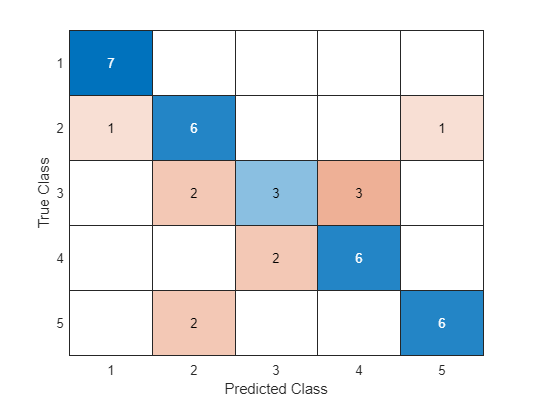

confusionchart(group, testClass)